# 1. Table of each year data converted in to structural arrays and output into a single workbook on separate sheets

clear
clc
% Input file path
kaggle_data_file = "C:\Users\EDDY\Documents\sub\Indian_water_data.xlsx";
Table = readtable(kaggle_data_file);

% Tables of each year of data
T_2022 = Table(Table.Year == 2022, :);
T_2023 = Table(Table.Year == 2023, :);

% Process data for each year
struct_arrays = struct();
unique_years = unique(Table.Year);
for i = 1:length(unique_years)
    year = unique_years(i);
    year_data = Table(Table.Year == year, :);
    currentYear = sprintf('Year_%d', year);

    % Store data in struct and Excel
    S = table2struct(year_data);
    struct_arrays(i).(currentYear) = S;
    writetable(year_data,"output.xlsx",'Sheet',currentYear);
end

## Data Visualization and plotting

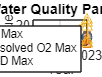

% Line plot: Year vs pH, Dissolved Oxygen, BOD
figure;
plot(Table.Year, Table{:,'pH_Max'}, '-o'); hold on;
plot(Table.Year, Table{:,'Dissolved_Max'}, '-s');
plot(Table.Year, Table{:,'BOD_mg_L__Max'}, '-^');
xlabel('Year'); ylabel('Value');
legend('pH Max','Dissolved O2 Max','BOD Max');
title('Trends of Key Water Quality Parameters Over Time');
grid on;
saveas(gcf,'Line_plot.png');

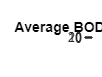


% Bar chart
figure;
avgState = Table.BOD_mg_L__Max;
bar(avgState);
xticklabels(Table.StateName); ylabel('BOD (mg/L)');
title('Average BOD by State');
xtickangle(45);
saveas(gcf,'Bar_chart.png');

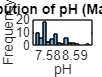


% Histogram of pH values
figure;
histogram(Table.("pH_Max"), 15);
xlabel('pH'); ylabel('Frequency');
title('Distribution of pH (Max Values)');
saveas(gcf,'Histogram.png');

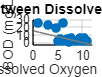


% Scatter plot Dissolved O2 vs BOD
figure;
scatter(Table.("Dissolved_Max"), Table.("BOD_mg_L__Max"), 'filled');
xlabel('Dissolved Oxygen (mg/L)');
ylabel('BOD (mg/L)');
title('Relationship between Dissolved Oxygen and BOD');
grid on;
lsline; % add regression line
saveas(gcf,'Scatter_plot.png');

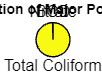


% Mean values of pollutants
pollutants = [mean(Table.("BOD_mg_L__Max"),'omitnan'), ...
              mean(Table.("NitrateN_mg_L__Max"),'omitnan'), ...
              mean(Table.("TotalColiform_MPN_100ml__Max"),'omitnan')];

labels = {'BOD','Nitrate','Total Coliform'};
figure;
pie(pollutants, labels);
title('Proportion of Major Pollutants');
saveas(gcf,'Pie_chart.png');

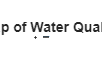


% Correlation matrix
vars = Table{:, {'pH_Max','BOD_mg_L__Max','Dissolved_Max','Conductivity___mho_cm__Max'}}; % Select reliable numeric variables
corrMatrix = corr(vars, 'Rows','complete');
figure;
heatmap({'pH','BOD','Dissolved O2','Conductivity'}, ...
        {'pH','BOD','Dissolved O2','Conductivity'}, ...
        corrMatrix);
title('Correlation Heatmap of Water Quality Parameters');
saveas(gcf,'Heat_map.png');

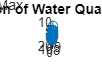


% 3D visualization of water quality parameters
figure;
plot3(Table.("pH_Max"), Table.("BOD_mg_L__Max"), Table.("Dissolved_Max"), 'o');
xlabel('pH Max'); ylabel('BOD Max (mg/L)'); zlabel('Dissolved O2 Max');
title('3D Visualization of Water Quality Parameters');
grid on;
saveas(gcf,'3D_Visualization.png');